# FSK demod 802.11b 1MB/s

load('test1.mat');

% Extract relevant information
waveform = waveStruct.waveform;
Fs = waveStruct.Fs;
time = (0:length(waveform)-1) / Fs;


## take every 11th value to simulate polling at 1MHz instead of 11MHz

nw = waveform(1:11:end,:);
Fs = Fs/11; %1e6
nt = (0:length(nw)-1) / Fs;


nw = lowpass(nw,4e5,Fs);

smallw = nw(1:length(nw)/64/4,:);
st = (0:length(smallw)-1) / Fs;
instantaneous_phase = unwrap(angle(hilbert(smallw)));

frequency_deviation = diff(instantaneous_phase) / (2 * pi * (nt(2) - nt(1)));

% Plot the waveform
figure;
plot(st, smallw);

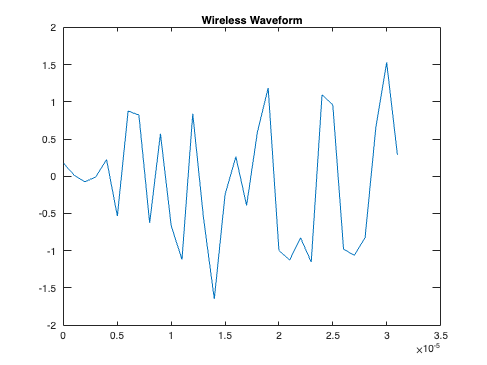

title('Wireless Waveform');

## Graph frequency-domain spectrium

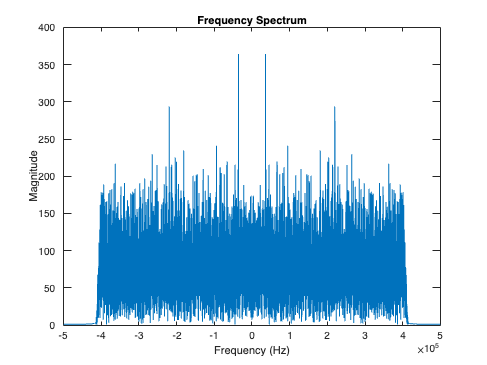

spectrum = fftshift(fft(nw));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

## Frequency shift

% Assuming 'signal' is your digital signal and 'sample_rate' is the sampling rate
t = nt;
negative_frequency_offset = 1.22e6;  % positive frequency offset in Hertz
shifter = exp(1i * 2 * pi * negative_frequency_offset * t);
shifter = shifter.';
shifted_signal = nw .* shifter;
%top_end = 1022000
%shifted_signal = lowpass(shifted_signal,top_end,Fs);
shifter = [];

smallw = shifted_signal(1:length(shifted_signal)/64/4,:);
st = (0:length(smallw)-1) / Fs;
instantaneous_phase = unwrap(angle(hilbert(smallw)));

frequency_deviation = diff(instantaneous_phase) / (2 * pi * (nt(2) - nt(1)));
figure;
plot(st, smallw);

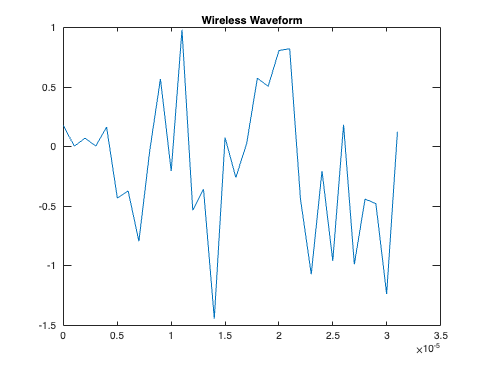

title('Wireless Waveform');

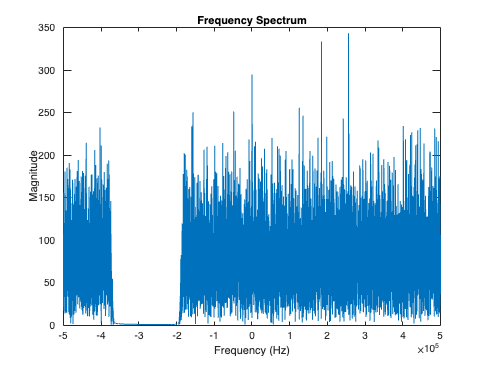



spectrum = fftshift(fft(shifted_signal));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');